# Constrained MHE Estimation - Constant Terminal Cost

clear 
close all
clc

rng('default')

## Set Path

addpath("simulation");
addpath("Optimization/UncOpt");
addpath("Optimization/ConsOpt");
addpath("simulation/SimulationData");

Urban = 0; % leave it to 0
real_meas = 0; 
max_time = 25;
min_time = 0.5;
Con = 1; % set to 1 if dealing with a constrained estimation problem

## Generate Measurement and Ground Truth Datasets

[ymeas_camera,ymeas_radar,N,time_vec,GT_state,min_index,max_index,ego_pos,ego_or] = get_meas(Con,Urban,real_meas,min_time,max_time);

## Filtering Algorithm

### Parameters of the Algorithm

nz = 5; % number of states
ny = 4; % number of measured output
nu = 2; % number of inputs (disturbances)
Ts = 0.1; % Filter/sensors sampling time
Ts_sim = 0.1; %0.01; % simulation sampling time, for optimization with simulation error method

#### Camera Covariance Matrix

As a general rule, lower values than radar

camera_x_var = 10; % better if higher
camera_y_var = 1; % better if lower
camera_v_x_var = 10; % better if higher
camera_v_y_var = 1; % better if lower
R_camera = diag([camera_x_var,camera_y_var,camera_v_x_var,camera_v_y_var])*eye(ny);


#### Radar Covariance Matrix

Higher values than camera

radar_x_var = 100; % better if lower
radar_y_var = 1000; % better if higher
radar_v_x_var = 100; % better if lower
radar_v_y_var = 1000; % better if higher
R_radar = diag([radar_x_var,radar_y_var,radar_v_x_var,radar_v_y_var])*eye(ny);

#### Process Covariance

long_acc_var = 1;
ang_acc_var = 1;
Q = diag([long_acc_var,ang_acc_var])*eye(nu);

#### Terminal Cost Covariance Matrix

A_terminal = 1e9*eye(nz);

#### Initial Guess

z_minus = [ymeas_radar(1,1);ymeas_radar(2,1);ymeas_radar(3,1);ymeas_radar(4,1);-7e-3]; % z(-M|1) initial state guess 

#### Optimizer Options

myoptions               =   myoptimset;
myoptions.Hessmethod  	=	'BFGS';
myoptions.gradmethod  	=	'CD';
myoptions.graddx        =	2^-17;
myoptions.tolgrad    	=	1e-8;
myoptions.ls_beta       =	0.2;
myoptions.ls_c          =	.01;
myoptions.ls_nitermax   =	1e2;
myoptions.nitermax      =	1e3;
myoptions.xsequence     =	'off';
myoptions.GN_sigma      = 1e-15;

### Filtering Algorithm

Msec            =   1;    % Seconds of Moving Horizon Estimator window
MHE_interval    =   1;      % number of steps after which optimization routine is repeated

% maximum allowed longitudinal and rotational accelerations (aka input disturbances)
a_max = 1e-6;
a_min = -1e-6;

alpha_max = 1e-9;
alpha_min = -1e-9;

[z_est,d_est,comp_time] = MHE_Con(Ts,Ts_sim,N,nz,ny,nu,Msec,MHE_interval,R_camera,R_radar,Q,A_terminal,z_minus,myoptions,ymeas_camera,ymeas_radar,a_max,a_min,alpha_max,alpha_min,ego_pos,ego_or);

Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    4.38454e+02   3.28923e+02   0.00000e+00   -1.00000e-01   1.00000e+00    1.00000e+00               0
        1    4.10163e+02   2.68148e+02   0.00000e+00   -9.99936e-02   1.17618e-01    3.06571e-01               6
        2    2.99074e+02   2.51576e+02   0.00000e+00   -9.99616e-02   4.14008e-02    8.98970e-02               5
        3    8.54858e+01   1.82251e+02   0.00000e+00   -9.59631e-02   2.26273e-01    1.93053e-01               2
        4    1.65920e+02   1.28881e+02   0.00000e+00   -9.21246e-02   2.55064e-01    2.83004e-01               2
        5    1.25801e+02   1.12219e+02   0.00000e+00   -8.84396e-02   1.18977e-01    1.10685e-01               2
        6    4.40624e+01   9.43754e+01   0.00000e+00   -7.07517e-02   1.61798e-01    2.06316e-01               1
        7    3.89193e+01   9.36056e+01   0.00000e+00   -7.01857e-02   8.15113e-03    4.64565e-02

mean_computational_time = mean(comp_time(Msec/Ts + 1 : end))

mean_computational_time = 0.0961

## Plot Results

### Relative Position

#### $x$ - Coordinate

## Plot Results

### Relative Position

#### $x$ - Coordinate

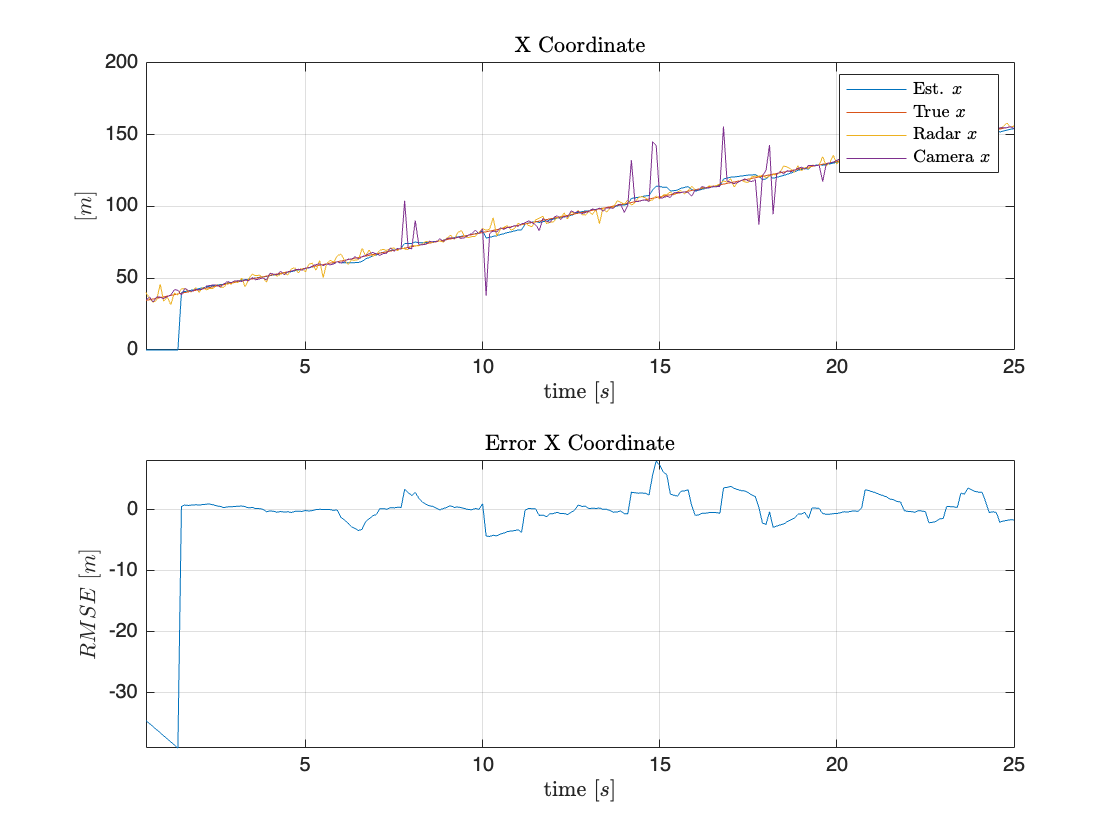

figure;
ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(1,:)), hold on
plot(time_vec,GT_state(:,1)), hold on
plot(time_vec,ymeas_radar(1,:)),hold on
plot(time_vec,ymeas_camera(1,:))
title('X Coordinate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m]$','Interpreter','latex')
legend('Est. $x$','True $x$','Radar $x$','Camera $x$','Interpreter','latex')

ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,(z_est(1,:)-GT_state(:,1)'))
title('Error~X Coordinate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$RMSE~[m]$','Interpreter','latex')
linkaxes(ax, 'x');
axis tight;

xlim([min_time max_time]);
hold off

#### 
$$x-\textrm{RMSE}$$


x_rmse = rmse(z_est(1,:),GT_state(:,1)')

x_rmse = 7.6716

#### $y$ - Coordinate

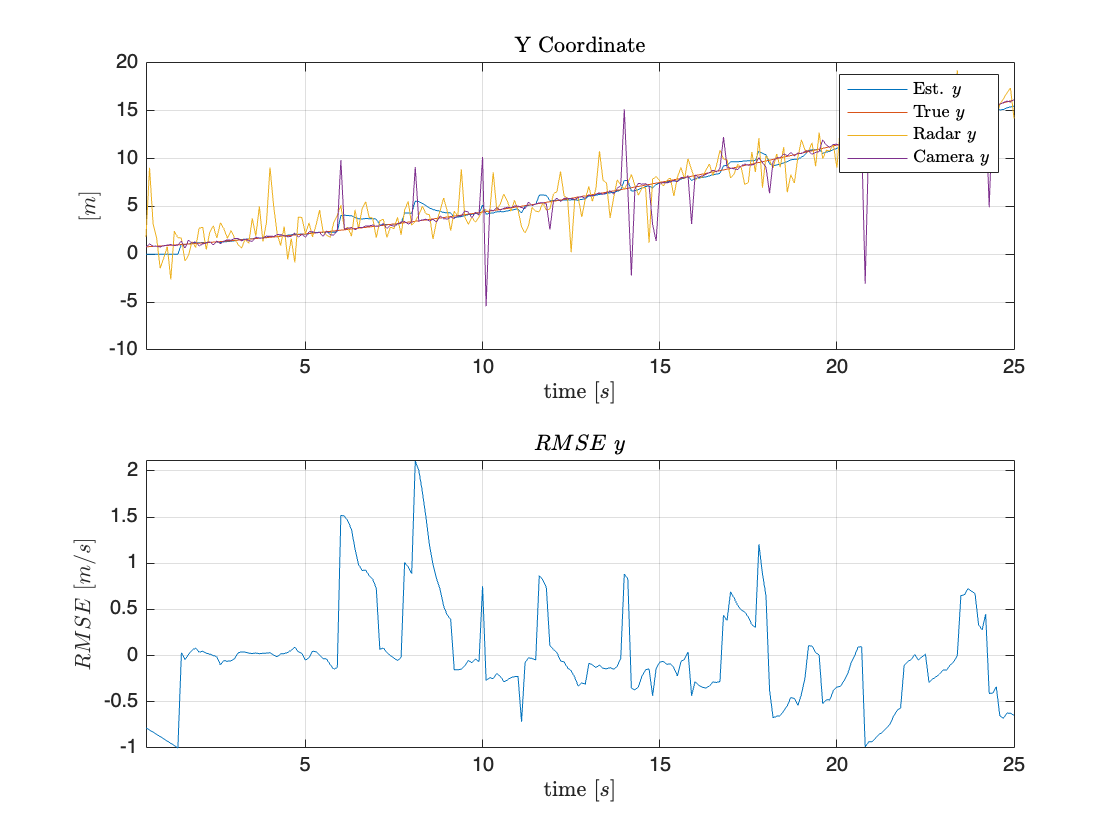

figure;
ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(2,:)), hold on
plot(time_vec,GT_state(:,2)), hold on
plot(time_vec,ymeas_radar(2,:)),hold on
plot(time_vec,ymeas_camera(2,:))
title('Y Coordinate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m]$','Interpreter','latex')
legend('Est. $y$','True $y$','Radar $y$','Camera $y$','Interpreter','latex')
ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,(z_est(2,:)-GT_state(:,2)'))
title('$RMSE~y$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$RMSE~[m/s]$','Interpreter','latex')
linkaxes(ax, 'x');
axis tight;
xlim([min_time max_time]);
hold off

#### 
$$y-\textrm{RMSE}$$


y_rmse = rmse(z_est(2,:),GT_state(:,2)')

y_rmse = 0.5454

### Velocities

#### 
$$v_x$$


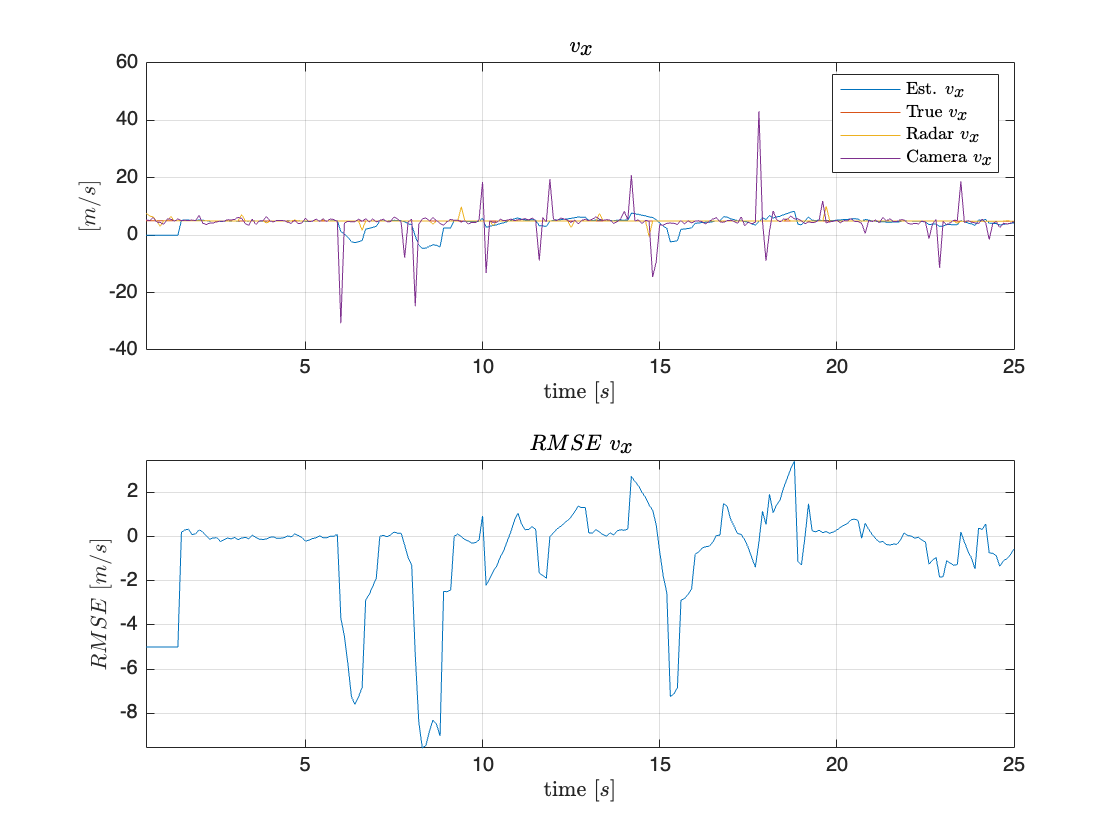

figure;
ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(3,:)), hold on
plot(time_vec,GT_state(:,3)), hold on
plot(time_vec,ymeas_radar(3,:)),hold on
plot(time_vec,ymeas_camera(3,:))
title('$v_x$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m/s]$','Interpreter','latex')
legend('Est. $v_x$','True $v_x$','Radar $v_x$','Camera $v_x$','Interpreter','latex')

ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,(z_est(3,:)-GT_state(:,3)')), hold on
title('$RMSE~v_x$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$RMSE~[m/s]$','Interpreter','latex')

linkaxes(ax, 'x');
axis tight;
xlim([min_time max_time]);
hold off


$$v_x -\textrm{RMSE}$$


v_x_rmse = rmse(z_est(3,:),GT_state(:,3)')

v_x_rmse = 2.4672

#### 
$$v_y$$


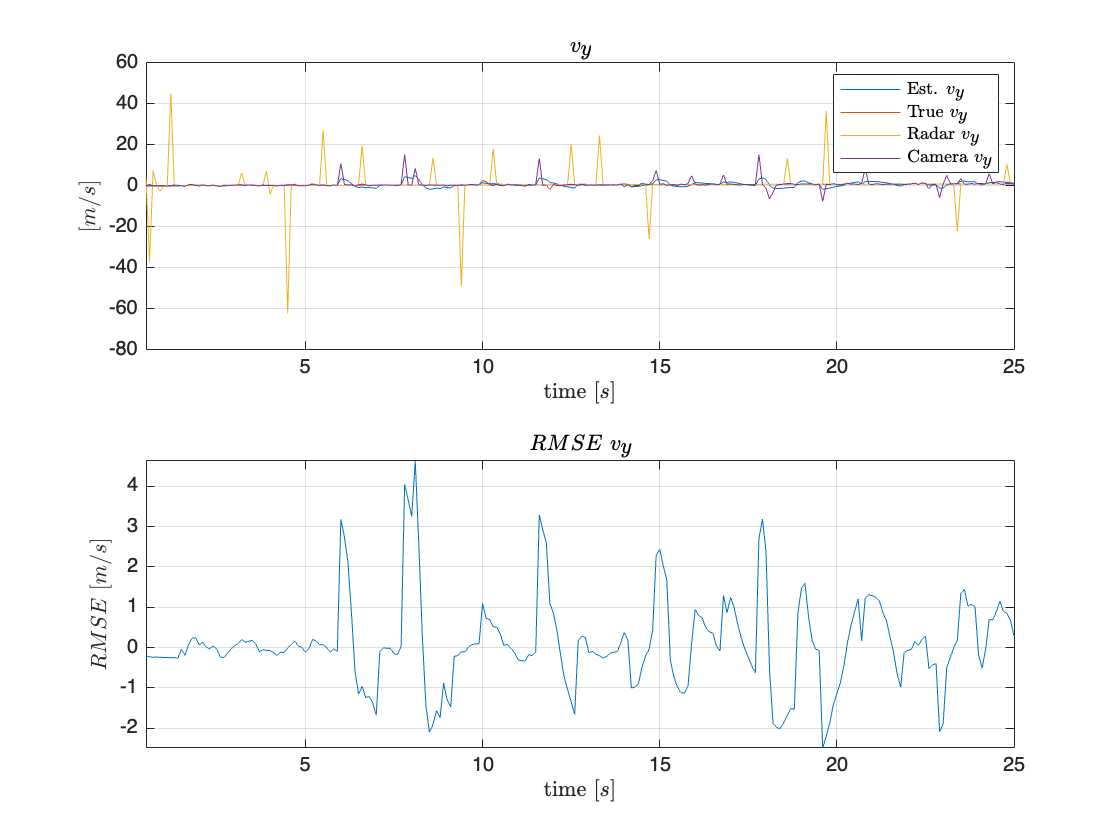

figure;
ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(4,:)), hold on
plot(time_vec,GT_state(:,4)), hold on
plot(time_vec,ymeas_radar(4,:)),hold on
plot(time_vec,ymeas_camera(4,:))
title('$v_y$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[m/s]$','Interpreter','latex')
legend('Est. $v_y$','True $v_y$','Radar $v_y$','Camera $v_y$','Interpreter','latex')

ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,(z_est(4,:)-GT_state(:,4)'))
title('$RMSE~v_y$','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$RMSE~[m/s]$','Interpreter','latex')
linkaxes(ax, 'x');
axis tight;
xlim([min_time max_time]);
hold off


$$v_{y\;} -\textrm{RMSE}$$


v_y_rmse = rmse(z_est(4,:),GT_state(:,4)')

v_y_rmse = 1.1075

#### Yaw Rate

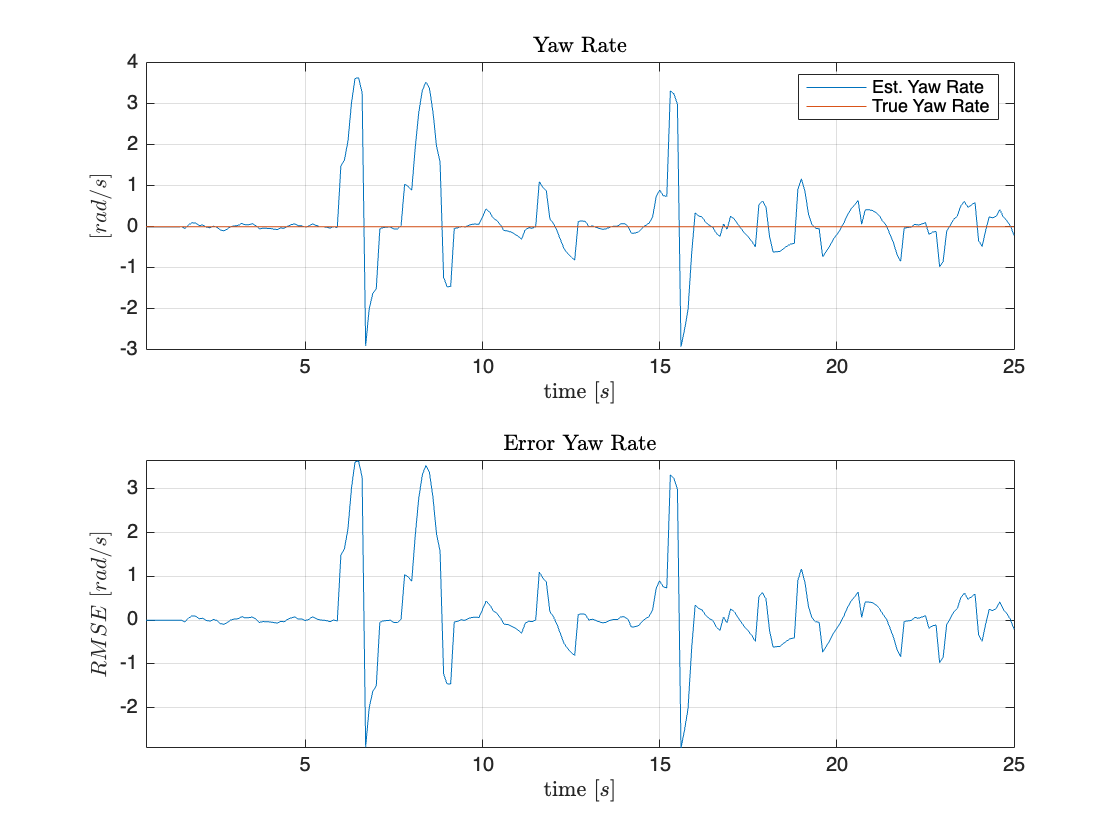

figure;
ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,z_est(5,:)), hold on
plot(time_vec,GT_state(:,5))
title('Yaw Rate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$[rad/s]$','Interpreter','latex')
legend('Est. Yaw Rate','True Yaw Rate')

ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,(z_est(5,:)-GT_state(:,5)'))
title('Error Yaw Rate','Interpreter','latex')
xlabel('time $[s]$','Interpreter','latex')
ylabel('$ RMSE~[rad/s]$','Interpreter','latex')
linkaxes(ax, 'x');
axis tight;
xlim([min_time max_time]);
hold off


$$\textrm{Yaw}\;\textrm{Rate}-\textrm{RMSE}$$


yaw_rate_rmse = rmse(z_est(5,:),GT_state(:,5)')

yaw_rate_rmse = 0.9362

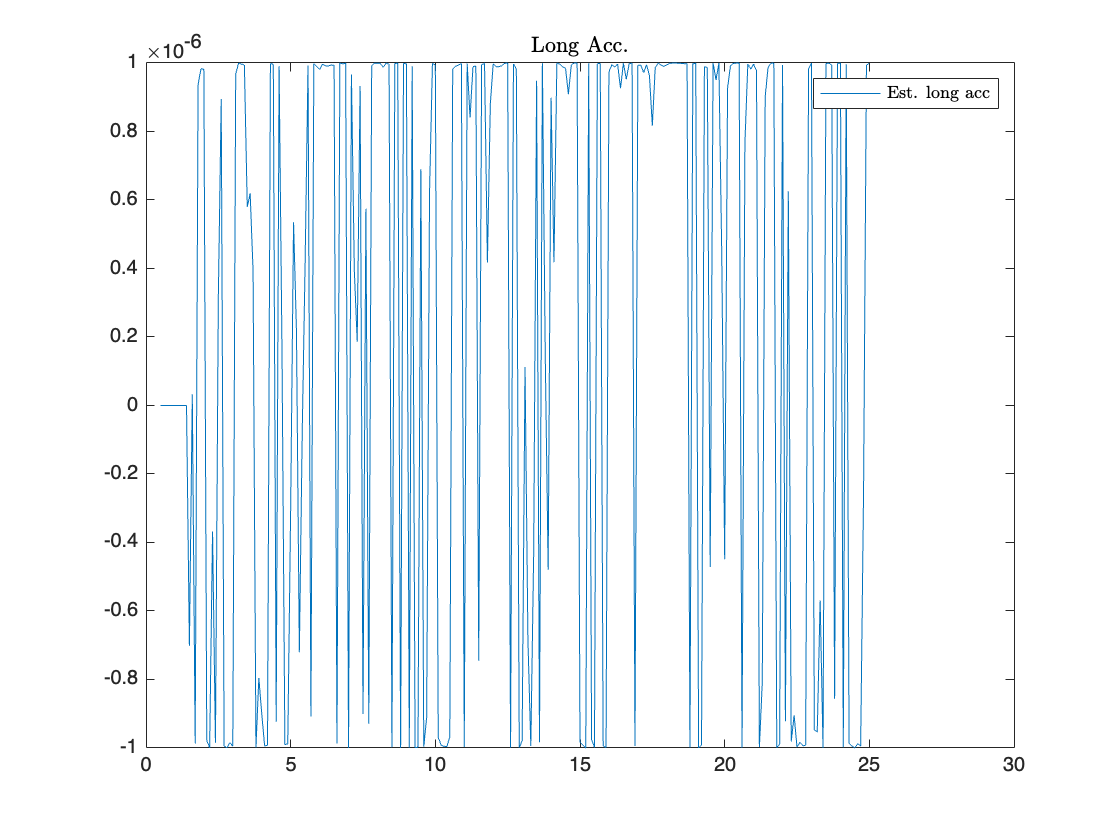

figure;
plot(time_vec,d_est(1,:)), hold on
title('Long Acc.','Interpreter','latex')
legend('Est. long acc','Interpreter','latex')
hold off

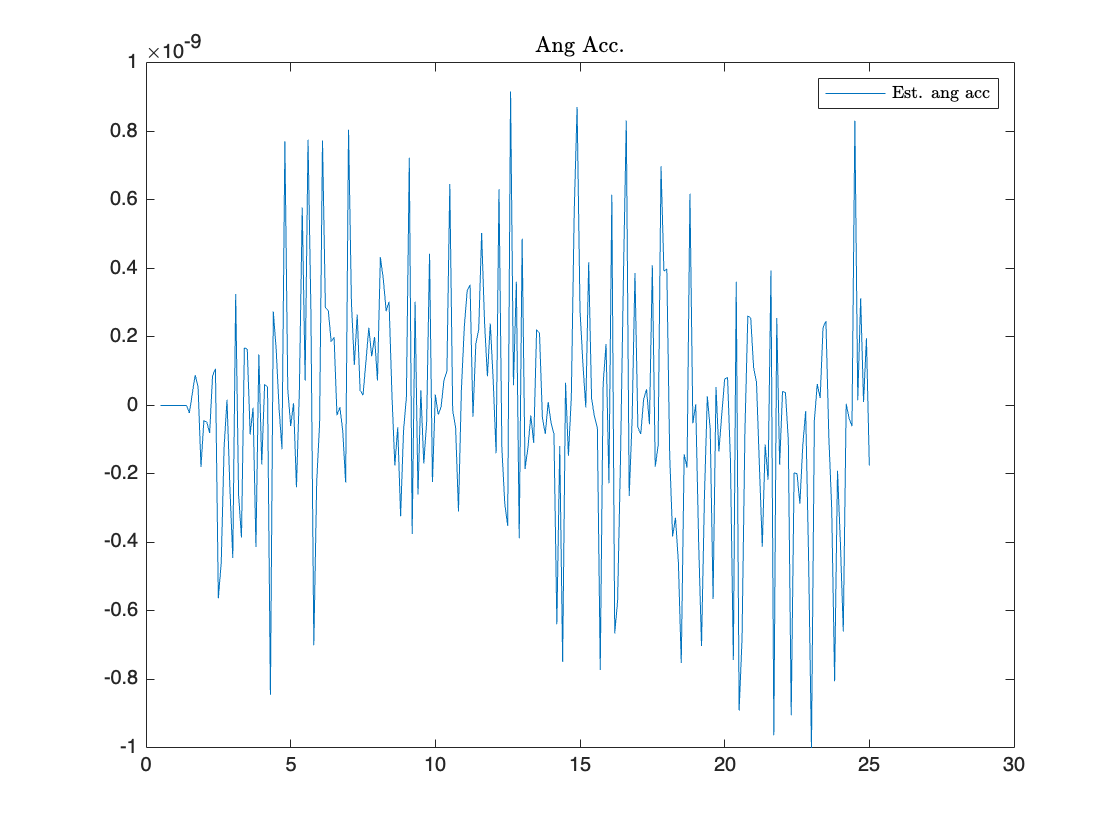

figure;
plot(time_vec,d_est(2,:)), hold on
title('Ang Acc.','Interpreter','latex')
legend('Est. ang acc','Interpreter','latex')
hold off